clc; clear; close all;

% Choosing file path for the data
[chosenfile,chosendirectory] = uigetfile({'*.xlsx';'*.csv'},...
            'Select Excel time series Data sets','data.xlsx');

filePath = [chosendirectory chosenfile];

% Loading the data into a series array of doubles
seriesData = readtable(filePath);
seriesData = table2array(seriesData(:,:));

% Step 2: Define the original time vector in seconds
% Assuming the data starts at time zero and is sampled every 5 minutes (300 seconds)
t_original = (0:length(seriesData)-1) * 5 * 60;  % 5 minutes = 300 seconds

% Step 3: Define the interpolated time vector in seconds, every 1 second
t_interp = 0:1:t_original(end);  % 1-second intervals

% Step 4: Perform spline interpolation
seriesData = spline(t_original, seriesData, t_interp)';
seriesDataCell  = num2cell(seriesData)';

% Converting into 5 day observation periods throughout the year
interval = 1; % Interval in days
seconds_per_day = 86400; % Total seconds in a day
obs_duration = interval * seconds_per_day; % Observation duration in seconds
obs_length = obs_duration / interval; % Number of data points per observation
num_obs = floor(length(seriesData) / obs_length); % Total number of observation periods

% Preallocate cell array
data = cell(num_obs, 1);

% Populate cell array with 3-day segments
for i = 1:num_obs
    startIdx = (i - 1) * obs_length + 1;
    endIdx = i * obs_length;
    data{i} = seriesData(startIdx:endIdx);
end

% Checking the data is in the correct format for training
numChannels = size(data{1},2)

numChannels = 1

figure
tiledlayout(2,2)
for i = 1:4
    nexttile
    stackedplot(data{i})
    title("Irradiance Observation " + i)
    xlabel("Time Step")
end

% Splitting the data into training and testing segments
trainingRatio = 0.9;
numObservations = numel(data);

idxTrain = 1:floor(trainingRatio*numObservations);
idxTest = floor(trainingRatio*numObservations)+1:numObservations;

dataTrain = data(idxTrain);
dataTest = data(idxTest);

% Preparing the data for training
numObservationsTrain = numel(dataTrain);
XTrain = cell(numObservationsTrain,1);
TTrain = cell(numObservationsTrain,1);
for n = 1:numObservationsTrain
    X = dataTrain{n};
    XTrain{n} = X(1:end-1,:);
    TTrain{n} = X(2:end,:);
end

% normalising the sequences to reduce the change of divergence
muX = mean(cell2mat(XTrain))

muX = 265.2552

sigmaX = std(cell2mat(XTrain),0)

sigmaX = 350.8578


muT = mean(cell2mat(TTrain));
sigmaT = std(cell2mat(TTrain),0);

for n = 1:numel(XTrain)
    XTrain{n} = (XTrain{n} - muX) ./ sigmaX;
    TTrain{n} = (TTrain{n} - muT) ./ sigmaT;
end

% Defining LSTM Architecture
layers = [
    sequenceInputLayer(numChannels)
    lstmLayer(128)
    fullyConnectedLayer(numChannels)];

options = trainingOptions("adam", ...
    MaxEpochs=200, ...
    SequencePaddingDirection="left", ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=false);


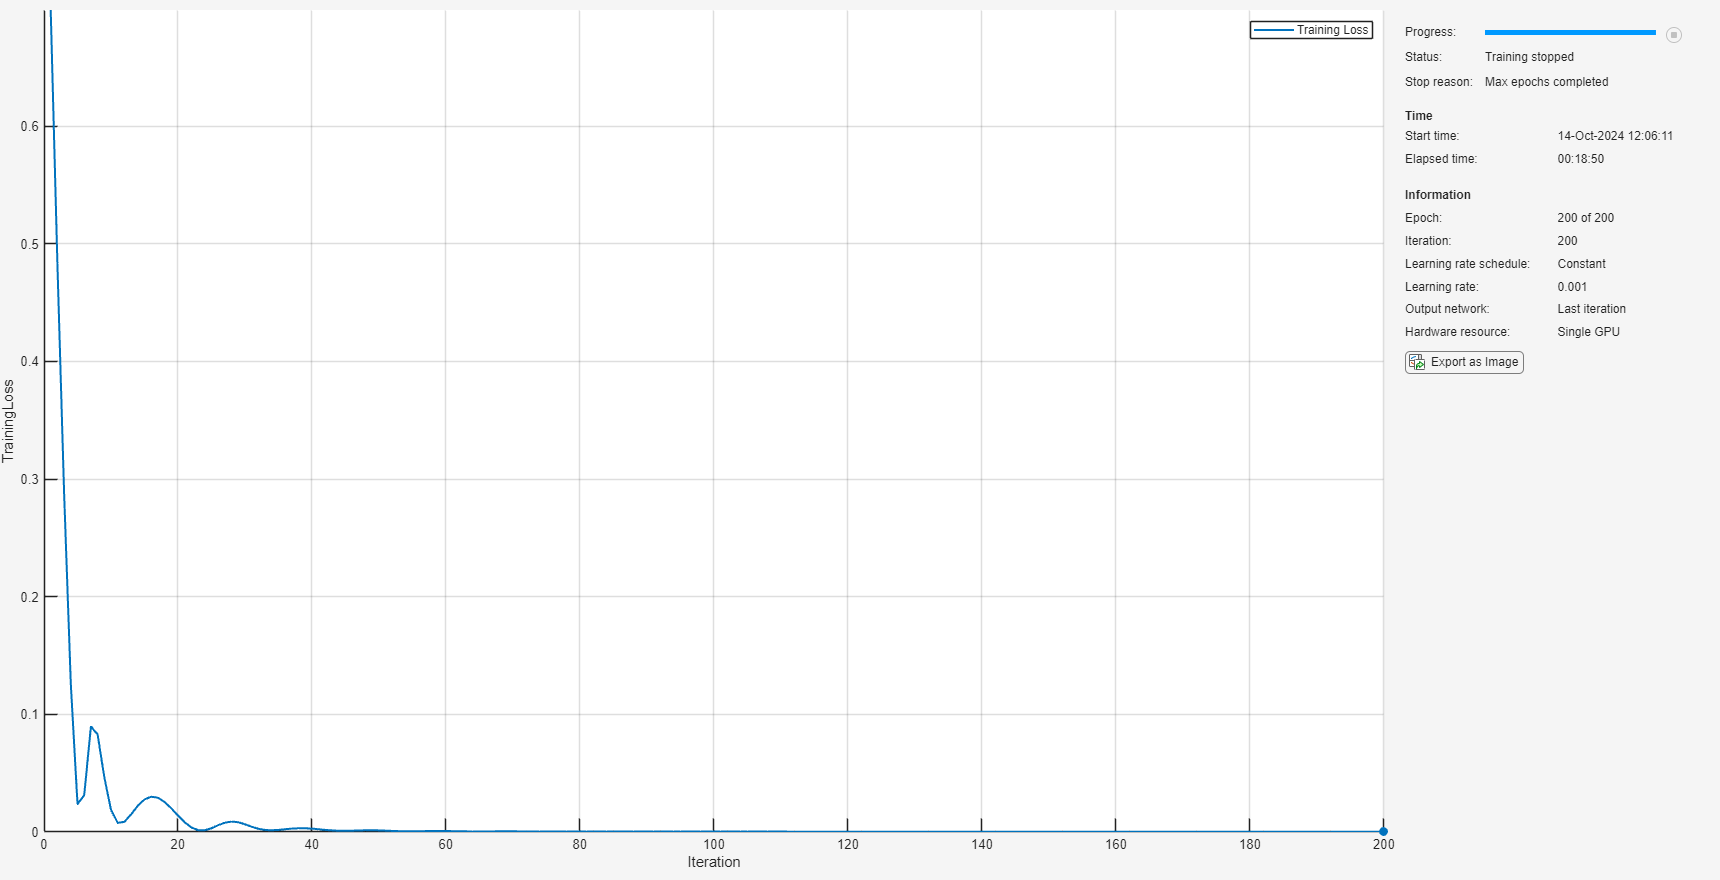

% Training the network (dual bi-lstm layer)
net = trainnet(XTrain,TTrain,layers,"mse",options);

% Saving the trained model
save('NET_LSTM_2023_irradiance_1s','net')

net = load('NET_LSTM_2023_irradiance');

% Testing the trained network net
numObservationsTest = numel(dataTest);
XTest = cell(numObservationsTest,1);
TTest = cell(numObservationsTest,1);
for n = 1:numObservationsTest
    X = dataTest{n};
    XTest{n} = (X(1:end-1,:) - muX) ./ sigmaX;
    TTest{n} = (X(2:end,:) - muT) ./ sigmaT;
end

YTest = minibatchpredict(net,XTest, ...
    SequencePaddingDirection="left", ...
    UniformOutput=false);

for n = 1:numObservationsTest
    T = TTest{n};

    sequenceLength = size(T,1);    

    Y = YTest{n}(end-sequenceLength+1:end,:);

    err(n) = rmse(Y,T,"all");
end

figure
histogram(err)
xlabel("RMSE")
ylabel("Frequency")
mean(err,"all")

ans = single
0.0145

% Open loop forecasting example
idx = 1;
X = XTrain{idx};
T = TTrain{idx};

figure
stackedplot(X,DisplayLabels="Channel " + (1:numChannels))
xlabel("Time Step")
title("Test Observation " + idx)
net = resetState(net);
offset = 10;
[Z,state] = predict(net, X(1:offset,:));
net.State = state;

numTimeSteps = size(X,1);
numPredictionTimeSteps = numTimeSteps - offset;
Y = zeros(numPredictionTimeSteps,numChannels);
Y(1,:) = Z(end,1);

for t = 1:numPredictionTimeSteps-1
    Xt = X(offset+t,:);
    [Y(t+1,:),state] = predict(net,Xt);
    net.State = state;
end

figure
t = tiledlayout(numChannels,1);
title(t,"Open Loop Forecasting")

for i = 1:numChannels
    nexttile
    plot(X(:,i))
    hold on
    plot(offset:numTimeSteps,[X(offset,i) Y(:,i)'],"-r")
end

xlabel("Time Step")
ylabel("Normalised Amplitude")
nexttile(1)
legend(["Input" "Forecasted"])

% Closed loop forcasting example
net = resetState(net);
offset = size(X,1);
[Z,state] = predict(net,X(1:offset,:));
net.State = state;

numPredictionTimeSteps = 1500;
Y = zeros(numPredictionTimeSteps,numChannels);
Y(1,:) = Z(end,:);

for t = 2:numPredictionTimeSteps
    [Y(t,:),state] = predict(net,Y(t-1,:));
    net.State = state;
end

numTimeSteps = offset + numPredictionTimeSteps;

figure
t = tiledlayout(numChannels,1);
title(t,"Closed Loop Forecasting")

for i = 1:numChannels
    nexttile
    plot(X(1:offset,i))
    hold on
    plot(offset:numTimeSteps,[X(offset,i) Y(:,i)'],"--")
    ylabel("Channel " + i)
end

xlabel("Time Step")
nexttile(1)
legend(["Input" "Forecasted"])
hold off

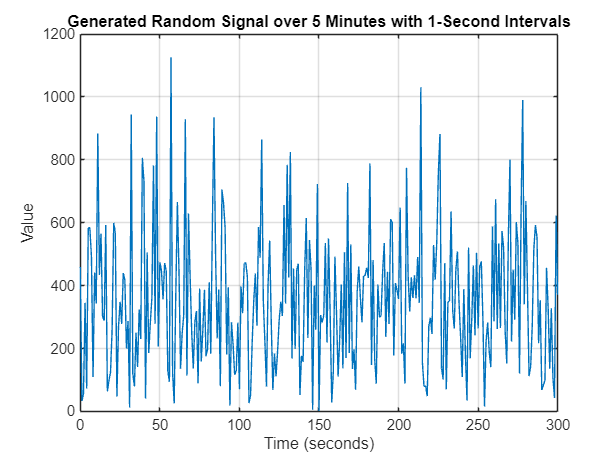

% Extract statistical data from seriesData sampled at 5-minute intervals
% Use the statistical data to generate a 5-minute random signal
% The signal ranges between 0 and 800 with 1-second intervals

% Assume 'seriesData' is a vector containing your data sampled at 5-minute intervals
% If 'seriesData' is not defined, please load or define it before running this code

% Extract statistical properties from seriesData
meanValue = mean(seriesData);
stdValue = std(seriesData);
minValue = min(seriesData);
maxValue = max(seriesData);

% Define the parameters for the random signal
lowerBound = 0;
upperBound = 1154;
duration = 5 * 60;  % 5 minutes in seconds
time = 0:1:duration;  % Time vector with 1-second intervals
nPoints = length(time);

% Generate a random signal with the same statistical properties
% We will use a truncated normal distribution to ensure values stay within [0, 800]

% Create a normal distribution object with the extracted mean and standard deviation
pd = makedist('Normal', 'mu', meanValue, 'sigma', stdValue);

% Truncate the distribution to the [0, 800] interval
t = truncate(pd, lowerBound, upperBound);

% Generate random numbers from the truncated normal distribution
randomSignal = random(t, nPoints, 1);

% Create a timeseries object for the random signal
ts_randomSignal = timeseries(randomSignal, time);
ts_randomSignal.Name = 'Generated Random Signal';
ts_randomSignal.TimeInfo.Units = 'seconds';

% Optional: Plot the generated random signal
figure;
plot(ts_randomSignal.Time, ts_randomSignal.Data);
xlabel('Time (seconds)');
ylabel('Value');
title('Generated Random Signal over 5 Minutes with 1-Second Intervals');
grid on;

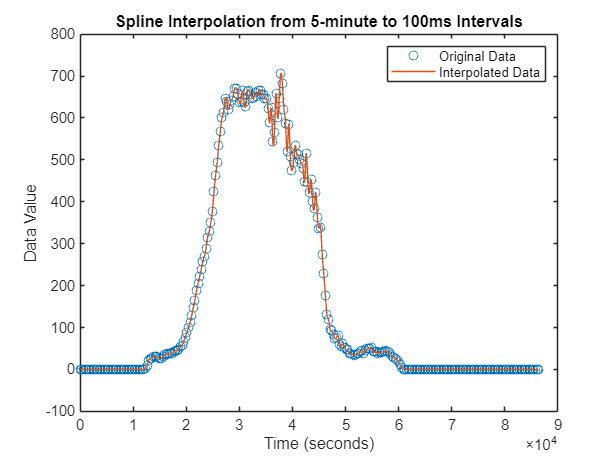

% Converting test data into time series for simulink
% Original data and timeseries from given snippet
daysLength = 1;  % Number of days for the given test data
startDay = 1; % 

start = (startDay - 1) * 288;
start = start + 1;

interval = daysLength * 288;
interval = start + interval;

testData = seriesData(start:interval)';

% Define the original time vector in seconds
t_original = (0:length(testData)-1) * 5 * 60;  % 5 minutes = 300 seconds

% Define the interpolated time vector in seconds, every 100ms
t_interp = 0:0.1:t_original(end);  % 100ms = 0.1 seconds

% Perform spline interpolation
interpData = spline(t_original, testData, t_interp);

% Optional: Plot the original and interpolated data
figure;
plot(t_original, testData, 'o', 'DisplayName', 'Original Data');
hold on;
plot(t_interp, interpData, '-', 'DisplayName', 'Interpolated Data');
legend;
xlabel('Time (seconds)');
ylabel('Data Value');
title('Spline Interpolation from 5-minute to 100ms Intervals');
hold off;

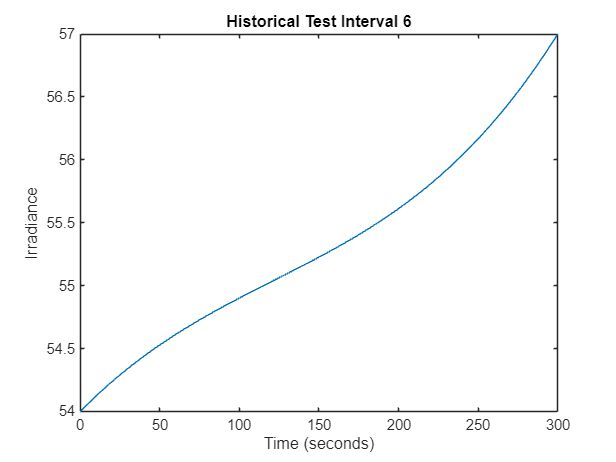

% Prompt the user to enter the start time in seconds
startTime = 18900;

% Define the end time (60 seconds after the start time)
endTime = startTime + 300;

% Find indices of t_interp that fall within the specified interval
indices = find(t_interp >= startTime & t_interp <= endTime);

% Extract the corresponding data and time points
data_5min = interpData(indices);
time_5min = t_interp(indices);

% Setting time to start at 0s
time_5min = time_5min - startTime;

% Create a timeseries object
ts = timeseries(data_5min, time_5min);
ts.Name = 'HistoricalTest1';
ts.TimeInfo.Units = 'seconds';
ts.TimeInfo.StartDate = '';  % Optional: specify a start date if available

plot(ts)
xlabel('Time (seconds)');
ylabel('Irradiance');
title('Historical Test Interval 6');

% Save the file if it is in the correct format
filename = 'historical_test_6.mat';
save(filename, 'ts');

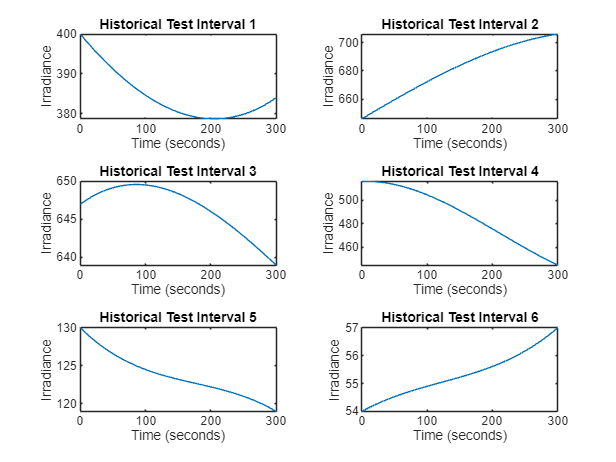

% Load the timeseries data from .mat files
ts1 = load('historical_test_1_resampled.mat').resampledTs;
ts2 = load('historical_test_2_resampled.mat').resampledTs;
ts3 = load('historical_test_3_resampled.mat').resampledTs;
ts4 = load('historical_test_4_resampled.mat').resampledTs;
ts5 = load('historical_test_5_resampled.mat').resampledTs;
ts6 = load('historical_test_6_resampled.mat').resampledTs;

figure
tiledlayout(3,2)
nexttile
plot(ts1)
xlabel('Time (seconds)');
ylabel('Irradiance');
title('Historical Test Interval 1');
nexttile
plot(ts2)
xlabel('Time (seconds)');
ylabel('Irradiance');
title('Historical Test Interval 2');

nexttile
plot(ts3)
xlabel('Time (seconds)');
ylabel('Irradiance');
title('Historical Test Interval 3');

nexttile
plot(ts4)
xlabel('Time (seconds)');
ylabel('Irradiance');
title('Historical Test Interval 4');

nexttile
plot(ts5)
xlabel('Time (seconds)');
ylabel('Irradiance');
title('Historical Test Interval 5');

nexttile
plot(ts6)
xlabel('Time (seconds)');
ylabel('Irradiance');
title('Historical Test Interval 6');

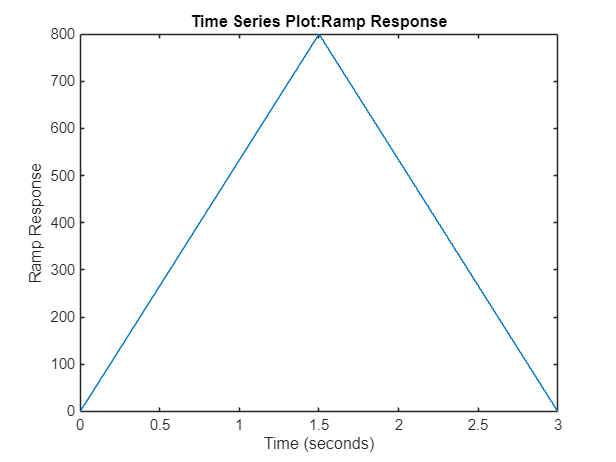

% Define the time vector from 0 to 10 seconds, sampled every 0.5 seconds
range = 3;
maxHeight = 800;
resolution = 0.01;

t1 = 0:resolution:range/2-resolution;
t2 = range/2:resolution:range;

t = 0:resolution:range;

m = maxHeight/(range/2);
c = maxHeight * 2;


% Define the ramp response (linear increase from 0 to maximum value)
% Here, the ramp increases from 0 to 10 over 10 seconds
ramp_data1 = m * t1;
ramp_data2 = -(m*t2) + c;

ramp_data = [ramp_data1, ramp_data2];

% Create a timeseries object
ts_ramp = timeseries(ramp_data, t);
ts_ramp.Name = 'Ramp Response';
ts_ramp.TimeInfo.Units = 'seconds';
ts_ramp.TimeInfo.StartDate = '';  % Optional: specify start date if needed

figure
plot(ts_ramp)